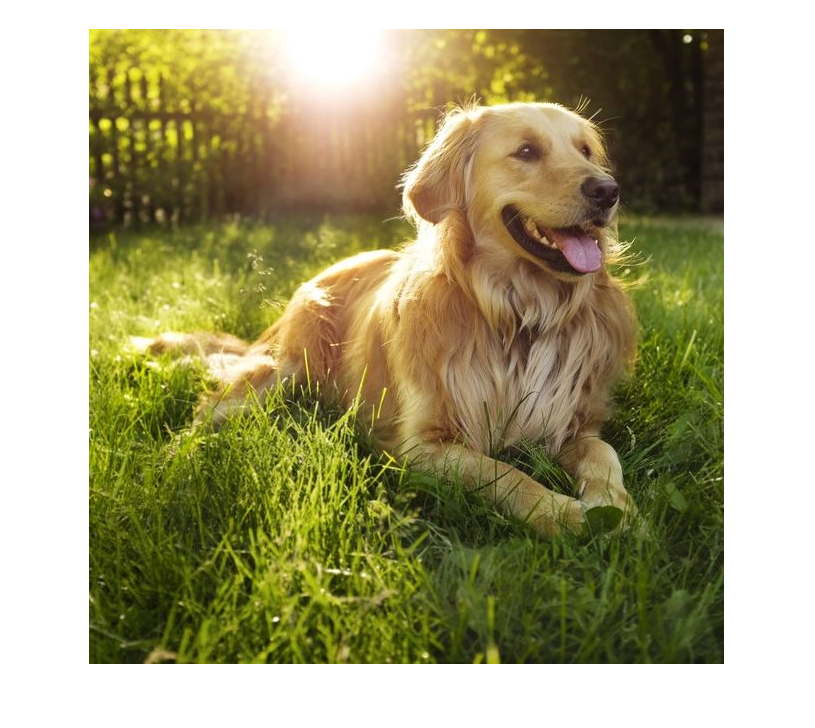

img = imread("squaredog.jpg");
imshow(img);



R = double(img(:,:,1));
G = double(img(:,:,2));
B = double(img(:,:,3));
 I = imread('cameraman.tif');
points = detectBRISKFeatures(I)

points =   428×1 BRISKPoints array with properties:

          Scale: [428×1 single]
    Orientation: [428×1 single]
       Location: [428×2 single]
         Metric: [428×1 single]
          Count: 428


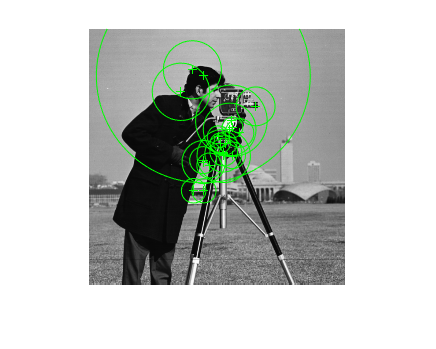

imshow(I);
hold on;
plot(points.selectStrongest(20))
hold off

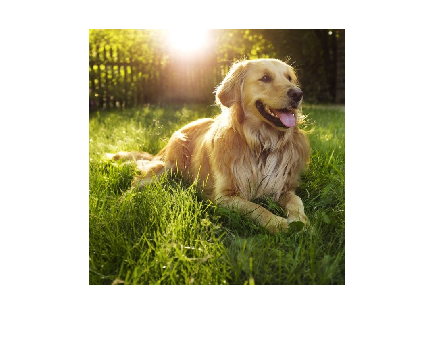

I = uint8((cat(3,R,G,B)));

%imagesc(uint8(R));
imshow(I);